# PHYS 361 Lab 2: Matrices and Arrays

## Basic Syntax Warm-Up

The arc length of a parabola ABC of a ellpse with a semi-major axes a and b is given approximately by:


$$L_{ABC}=\frac{1}{2}\sqrt{(b^2+16a^2)}+\frac{b^2}{8a}ln\left(\frac{4a+\sqrt{b^2+16a^2}}{b}\right)$$


Determine $L_{ABC}$ when $a=11$in and $b=9 $in.

## Array Warm-Up Element by Element Operations

**THIS IS IMPORTANT! **Sometimes you want to multiple or divide or exponentiate an every element in an array.  You can do that in MATLAB, but you need to use **special notation (.* , .^ , ./ ) .**  


$$a= \pmatrix{a_1 & a_2 & a_3 }\\
b=\pmatrix{b_1 & b_2 & b_3 }\\
a.*b=\pmatrix{a_1b_1 & a_2b_2 & a_3b_3 }\\
a./b=\pmatrix{a_1/b_1 & a_2/b_2 & a_3/b_3 }\\
a.^b=\pmatrix{a_1^{b_1} & a_2^{b_2} & a_3^{b_3} }\\
$$


**Examples**:

%Element-by-element multiplication, division, and exponentiation
A = [1 2 3]
B = [4 5 6]
A.*B
A./B
A.^2
B.^2
A.^B

Note even doing the following would get you introuble using the matrixes defined above


$$A^{2}$$


because that is the same as A*A and the dimensions do not agree.  If you wan to square each element in A you must use the element-by-element notation:

A^2     %Doesn't work because # of columns is not the same as rows

A.^2    %Works because it is squaring every element

Define the vector $x=[1,2,3,4,5]$ and $y=\left\lbrack 2,4,6,8,10\right\rbrack$.

Use these vectors to calculate the following using element-by-element operations.

(a) $z=\frac{(x+y)^2}{x-y}$          (b) $w=x ln(x^2+y^2)+\sqrt{\frac{y^3}{(y-x)^3}$

## Problem 1: Solving a Linear Set of Equations

MATLAB is designed to do the type of matrix operations you would do in a linear algebra course.  Run and try to understand the example code below.

Addition and subtraction is done element-by-element, so matrices and arrays have to be the same size.

vectA=[8 5 4]; 
vectB=[10 2 7];
vectA+vectB
vectA-vectB

If you multiply or divide an array or matrix by a scalar, every element is multiplied or divided.

vectA*2
vectA/2

If you multiple two matrixes using *, it will do it the linear algebra way (matrix multiplication):

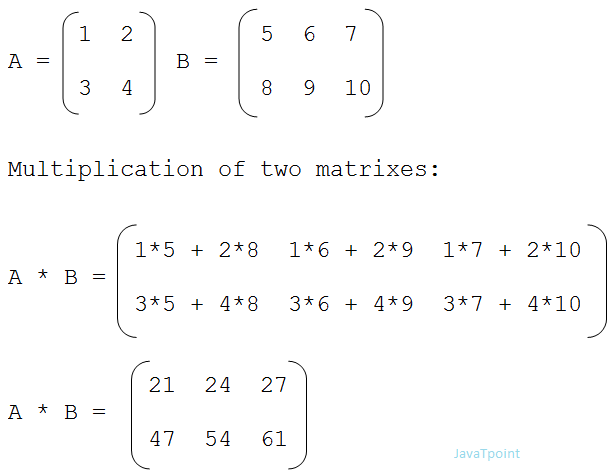

This means if you are taking A*B then A must have the same number of columns as the number of rows in B (like in the example above).  

A = [1 2; 3 4];            %Define A and B
B = [5 6 7; 8 9 10];

size(A)                    %Print the dimension
size(B)

C=A*B                      %Multiply 

size(C)                    %Show the dimensions of results

Matrix division is a little more complex. MATLAB can do two different forms of division: left division (\) and right division (/).

If you have a matrix problem that you want to solve that looks like this:

$AX=B$.

You can find the solution by multiplying both sides by the inverse of A ($A^{-1}$):


$$A^{-1}A=I$$


where I is the identity matrix. Therefore,


$$A^{-1}AX=IX=X$$


So the solution to the original equations is:


$$X=A^{-1}B$$


In MATLAB, this is the same as doing what it calls left division:


$$X=A \backslash B$$


On the other hand, you might need to solve this equation for X:


$$XC=D$$


Since *X* and *C* are matrices, you can't just switch the order of X and C (it's not communative).  However, you can multiply the right hand side of each equation by the inverse of C.  


$$XCC^{-1}=DC^{-1}$$



$$X=DC^{-1}$$


In MATLAB this is the same as doing right hand division:


$$X=D/C$$


**Example: **Solving a system of linear equations.


$$4x-2y+6z=8 \\
2x+8y+2z=4 \\
6x+10y+3z=0 $$


You have three equations and three unknowns; therefore, through substitution and algebra, you could solve them by hand. OR you could write it as a matrix problem.


$$ \pmatrix{4 & -2 & 6 \cr 
               2 & 8 & 2 \cr 
               6 & 10 & 3} 
 \pmatrix{x \cr 
               y\cr 
               z} =
 \pmatrix{8 \cr 
               4\cr 
               0} 
$$


We can rewrite this problem by defining matrixes *A, X,* and *B*, where *AX=B*. Then we can use MATLAB to solve for X using left hand division:

A=[4 -2 6; 2 8 2; 6 10 3];
B = [8; 4; 0];              %Note I made this a column array so the dimensions work
X=A\B                       %Using left division 
A*X                         %Confirming I did it right, should be equal to B

Since X = [ x y z], I know x=8, y=4, and c=0 in the system of equations I started with.

## Problem 1:

Solve the following system of linear equations


$$-4 x +3y+z=18.2 \\
5x+6y-2z= -48.4 \\
2x-5y+4.5z=92.5
$$


Write an additional line of code to prove you are correct.

## Problem 2:

In this problem, you will analyze the following circuit:

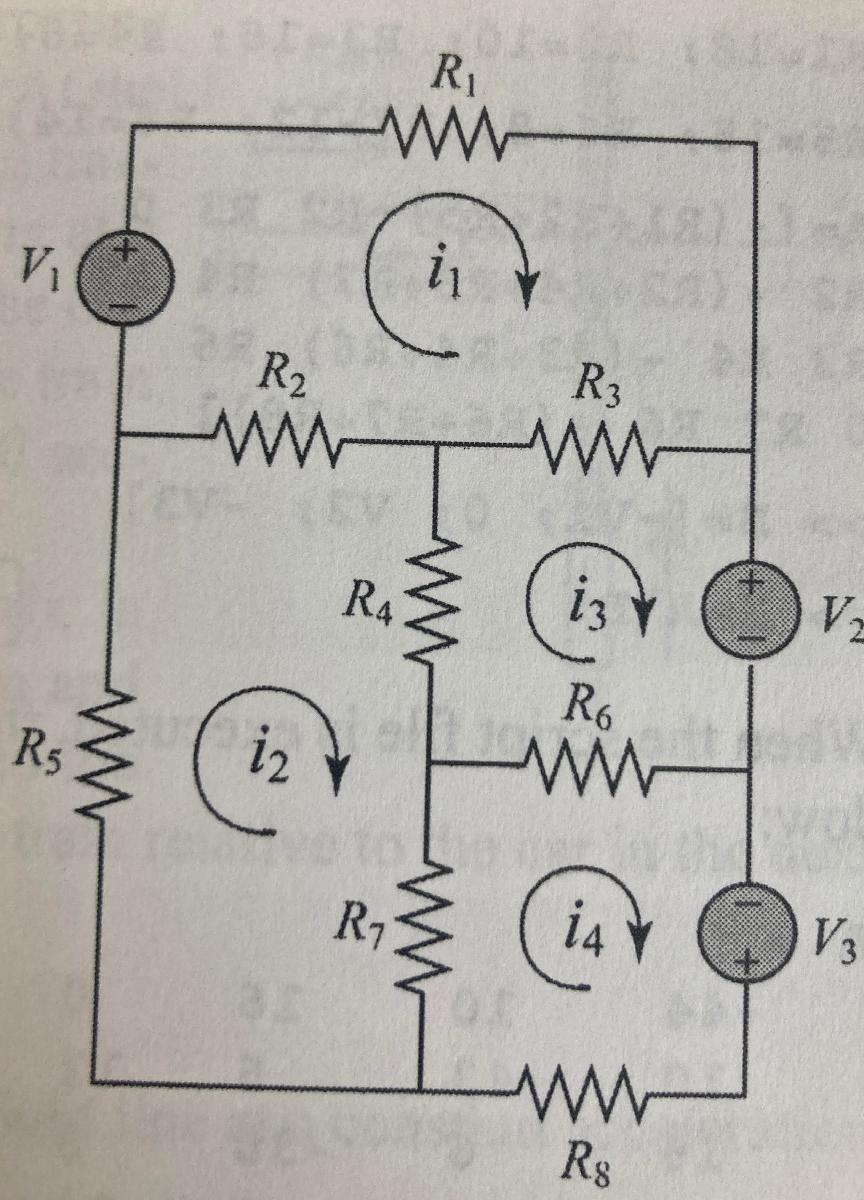 

**Kirchoff's voltage law** states that the sum of the voltage around a closed circuit is zero. The sources and sinks of voltage along the loops can be batteries (labeled as V above) and resistors labeled as R. The change over a resistor is always negative and given by Ohm's Law, $\Delta V=iR$.

The **mesh current law** states that the current going through any resistor is equal to the sum of the current in connecting "meshes" or loops.  For example, $R_{2}$, in the top loop connected to two meshes (or rectangles of wire).  It is standard to assume that the  current is moving in the clockwise direction over each loop. That means there is current moving from right to left through $R_{1}$ from the top mesh and left to right through $R_{1}$ from the bottom mesh. Therefore, if we call the current moving through the top mesh $i_1$ and the bottom mesh (connected to $R_{1}$ ) $i_2$ the current going through $R_{1}$ is,


$$i_1=(i_1-i_2)$$


Lets use this convention along the whole top loop, Kirchoff's law gives us the following equation,

                        $V_1-R_1i_1-R_3(i_1-i_3)-R_2(i_1-i_2)=0$.

Since we are writing the equation for the top loop or loop 1, the current going through that loop, $i_1$, is always positive and the opposing current is always subtracted from it.

**Let's analyze this system:**

**Step 1: **By hand, write out three more equations describing the sum of voltages along the other 3 closed loops. Have the instructor check your work.

**Step 2:** Reorganize these equations (by hand) to that they can be written in the following form


$$RI=V$$


where R and V are matrices that include the resistance (R) and voltage (V) terms and 


$$I=\pmatrix{i_a \cr i_b \cr i_c \cr i_d}$$


**Step 3:** In MATLAB, define the following variables 


$$V_1=20 V,V_2=12V,V_3=40V$$



$$R_1=18\Omega,R_2=10\Omega,R_3=16\Omega, R_4=6\Omega, R_5=15\Omega, R_6=8\Omega, R_7=12\Omega, R_8=14\Omega$$


**Step 4: **Use matrix algebra to solve for the current in each loop (given by the array defined above).

## Problem 3: The idea gas law

The ideal gas law is 


$$P=\frac{nRT}{V}$$


where P is the pressure, V is the volume, T is the temperature,  R is the gas constant (R=0.08206 (L atm)/(mol K)), and n is the number of moldes.  Real gases, especially at high temp, deviate from this behavior.  Their response can be modeled with the van der Waals equation


$$P=\frac{nRT}{V-nb}-\frac{n^2a}{V^2}$$


where a and b are material constants.  Consider 1 mole (n=1) of nitrogen gas at T=50 K.  For nitrogen, a=1.39 (L^2 atm)/mol^2 and b=0.0391 L/mol.  

**Step 1:** Creat a vector with values of volume (V) for $0.1 \le V  \le1$L, using increments of 0.02 L. 

**Step 2: **Using this vector calculate P twice for each value of V, once using the ideal gas equation and once using the van der Waals equation.  

**Step 3:** Using the two sets of values for P, calcualte the percent error $\left|\left(\frac{P_{ideal}-P_{waals}}{P_{waals}}\right)\times100\right|$.  You should use the built-in function `abs`.

**Step 4: **Finally, using MATLAB's built-in fuction `max`, determine the maximum error and the corresponding volume. (Hint: Look at the help file for the max function to discover all the possiblities.)